**Nonlinear Support Vector Machine**

Consider the training data given. Find the nonlinear regression function given by the nonlinear SVM using a Gaussian kernel with γ = 1 and parameters ε = 0.3, C = 10. Moreover, find the support vectors.

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

data = [ 0    0.0620
    0.1000    0.2247
    0.2000    0.4340
    0.3000    0.6490
    0.4000    0.7370
    0.5000    0.8719
    0.6000    0.9804
    0.7000    1.0192
    0.8000    1.0794
    0.9000    1.0726
    1.0000    0.9252
    1.1000    0.8322
    1.2000    0.7457
    1.3000    0.5530
    1.4000    0.4324
    1.5000    0.2384
    1.6000    0.0060
    1.7000   -0.1695
    1.8000   -0.4023
    1.9000   -0.5487
    2.0000   -0.6583
    2.1000   -0.8156
    2.2000   -0.8582
    2.3000   -0.9217
    2.4000   -0.9478
    2.5000   -0.8950
    2.6000   -0.7947
    2.7000   -0.7529
    2.8000   -0.5917
    2.9000   -0.3654
    3.0000   -0.2392
    3.1000   -0.0172
    3.2000    0.2067
    3.3000    0.4111
    3.4000    0.5594
    3.5000    0.6678
    3.6000    0.7973
    3.7000    0.9605
    3.8000    1.0246
    3.9000    1.0947
    4.0000    1.0640
    4.1000    1.0070
    4.2000    0.9069
    4.3000    0.7604
    4.4000    0.6811
    4.5000    0.4661
    4.6000    0.2259
    4.7000    0.0944
    4.8000   -0.1224
    4.9000   -0.3606
    5.0000   -0.4550
    5.1000   -0.6669
    5.2000   -0.8049
    5.3000   -0.9114
    5.4000   -0.9498
    5.5000   -0.9771
    5.6000   -0.9140
    5.7000   -0.9127
    5.8000   -0.7953
    5.9000   -0.6653
    6.0000   -0.4486
    6.1000   -0.3138
    6.2000   -0.0900
    6.3000    0.0940
    6.4000    0.3098
    6.5000    0.4316
    6.6000    0.6899
    6.7000    0.8252
    6.8000    0.8642
    6.9000    0.9903
    7.0000    1.0232
    7.1000    1.0610
    7.2000    0.9887
    7.3000    0.9528
    7.4000    0.8486
    7.5000    0.7103
    7.6000    0.5312
    7.7000    0.3067
    7.8000    0.1591
    7.9000   -0.0511
    8.0000   -0.2771
    8.1000   -0.4264
    8.2000   -0.5930
    8.3000   -0.7232
    8.4000   -0.8070
    8.5000   -0.8913
    8.6000   -0.9097
    8.7000   -0.9874
    8.8000   -0.9269
    8.9000   -0.8212
    9.0000   -0.6551
    9.1000   -0.5258
    9.2000   -0.3894
    9.3000   -0.2136
    9.4000   -0.0436
    9.5000    0.2240
    9.6000    0.3940
    9.7000    0.5431
    9.8000    0.7247
    9.9000    0.8305
   10.0000    0.9881];

x = data(:,1);
y = data(:,2);
l = length(x); % number of points

plot(x,y,'b.');

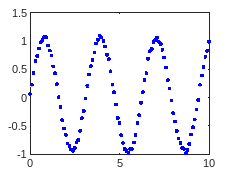


%% nonlinear regression - dual problem

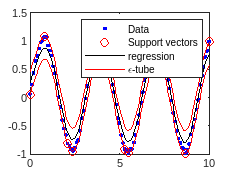


epsilon = 0.2;
C = 10;


% define the problem
X = zeros(l,l);
for i = 1:l
    for j = 1:l
        X(i,j) = kernel(x(i),x(j)) ;
    end
end
Q = [ X -X ; -X X ];
c = epsilon*ones(2*l,1) + [-y;y]; 

% solve the problem
options = optimset('Display', 'off');
solution = quadprog(Q,c,[],[],[ones(1,l) -ones(1,l)],0,zeros(2*l,1),C*ones(2*l,1), [], options);
lap = solution(1:l);
lam = solution(l+1:2*l);

% compute b
ind = find(lap > 1e-3 & lap < C-1e-3);
if ~isempty(ind)
    i = ind(1);
    b = y(i) - epsilon;
    for j = 1:l
        b = b - (lap(j)-lam(j))*kernel(x(i),x(j));
    end
else
    ind = find(lam > 1e-3 & lam < C-1e-3);
    i = ind(1);
    b = y(i) + epsilon ;
    for j = 1:l
        b = b - (lap(j)-lam(j))*kernel(x(i),x(j));
    end
end

% find regression and epsilon-tube
z = zeros(l,1);
for i = 1:l
    z(i) = b ;
    for j = 1:l
        z(i) = z(i) + (lap(j)-lam(j))*kernel(x(i),x(j));
    end
end
zp = z + epsilon ;
zm = z - epsilon ;


% find support vectors
sv = [find(lap > 1e-3)
      find(lam > 1e-3)]; 
sv = sort(sv);

%% plot the solution
plot(x,y,'b.',x(sv),y(sv),...
    'ro',x,z,'k-',x,zp,'r-',x,zm,'r-');

legend('Data','Support vectors',...
    'regression','\epsilon-tube',...
    'Location','NorthEast')

function v = kernel(x,y)
    %% kernel function
    gamma = 1 ;
    v = exp(-gamma*norm(x-y)^2);
end